%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% AAE 338
% Comparative Analysis Script
% Author: Travis Hastreiter, Cole Higgins
% Created On: 21 October, 2024
% Description: Analyzes the performance different radiator types accross
% different spacecraft thermal control regimes.
% Most Recent Change: Travis Hastreiter 21 October, 2024
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Parameters Initialization

Qdot_needed = 1:10:1000; % [W]

## Radiator Initialization

#### Pipe Radiator

pipe_radiators = PipeRadiator([], "H2O", 1000, 0.5, 10, 0.2);

#### Curie Point Radiators

cp_data = table;
cp_data.coolant_name = ["MysteryParticleA", "MysterParticleB"]';
cp_data.coolant_density = [5000, 4000]'; % [kg / m3]
cp_data.particle_diameter = [1e-4, 1e-3]'; % [m]
cp_data.emissivity = [0.8, 0.75]';
cp_data.curie_point = [800, 500]';

curie_point_radiators = CuriePointRadiator.CreateRadiators(cp_data);

#### Liquid Droplet Radiators

lq_data = table;
lq_data.coolant_name = ["MysteryFluidA", "MysterFluidB"]';
lq_data.coolant_density = [2000, 1000]'; % [kg / m3]
lq_data.droplet_velocity = [1, 0.5]'; % [m]
lq_data.emissivity = [0.8, 0.75]';
lq_data.flow_rate = [5, 10]';

liquid_droplet_radiators = LiquidDropletRadiator.CreateRadiators(lq_data);

#### Combine Radiators

radiators = [pipe_radiators; curie_point_radiators; liquid_droplet_radiators]

radiators = 5×1 heterogeneous Radiator ( PipeRadiator , CuriePointRadiator , LiquidDropletRadiator ) array with no properties.


pipe_indices = 1:numel(pipe_radiators);
cp_indices = (numel(pipe_radiators) + 1):(numel(pipe_radiators) + numel(curie_point_radiators));
lq_indices = (numel(pipe_radiators) + numel(curie_point_radiators) + 1):numel(radiators);

## Calculations

m = radiators.evaluate_mass_for_required_Qdot(Qdot_needed);
P = radiators.evaluate_power_for_required_Qdot(Qdot_needed);
size = radiators.evaluate_size_for_required_Qdot(Qdot_needed);

## Plots

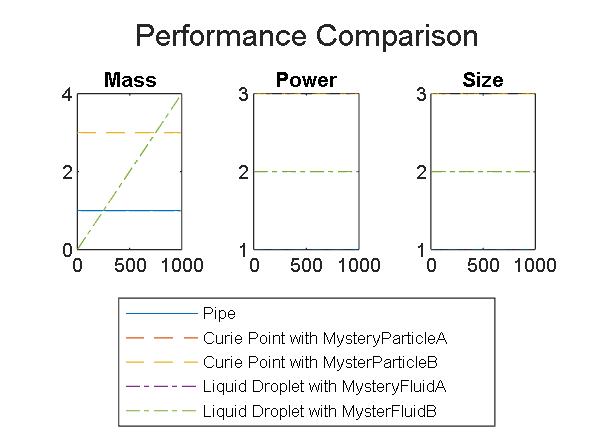

tiledlayout(1,3);
nexttile()
plot(Qdot_needed, m(pipe_indices, :)', LineStyle="-"); hold on
plot(Qdot_needed, m(cp_indices, :)', LineStyle="--")
plot(Qdot_needed, m(lq_indices, :)', LineStyle="-."); hold off
title("Mass")

nexttile()
plot(Qdot_needed, P(pipe_indices, :)', LineStyle="-"); hold on
plot(Qdot_needed, P(cp_indices, :)', LineStyle="--")
plot(Qdot_needed, P(lq_indices, :)', LineStyle="-."); hold off
title("Power")

nexttile()
plot(Qdot_needed, size(pipe_indices, :)', LineStyle="-"); hold on
plot(Qdot_needed, size(cp_indices, :)', LineStyle="--")
plot(Qdot_needed, size(lq_indices, :)', LineStyle="-."); hold off
title("Size")

lgd = legend(radiators.Name, Location="southoutside");
lgd.Layout.Tile = 'south';
sgtitle("Performance Comparison");